% AE6511 Hw6 Problem 5 (CH7 Method) MATLAB code
% Tomoki Koike 
clear all; close all; clc;  % housekeeping commands
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

% Define matrices 
R1 = 0;
R2 = 2;
A = [0 1; -1 0];
B = [0; 1];
x0 = [1; 2];
xf = [0; 0];

% tf = 10
tf = 10;

syms s t
assume(s, 'real');
assume(t, 'real');
W(t) = int(expm(A*s)*B*inv(R2)*B.'*expm(A.'*s),s,0,t)

$$W(t) = \left(\begin{array}{cc} 0.2500\,t-0.1250\,\sin\left(2\,t\right) & 0.2500\,{\sin\left(t\right)}^{2}\\ 0.2500\,{\sin\left(t\right)}^{2} & 0.2500\,t+0.1250\,\sin\left(2\,t\right) \end{array}\right)$$

p0 = expm(A.'*tf)*inv(W(tf))*(expm(A*tf) * x0 - xf)

$$p0 = \left(\begin{array}{c} 0.4432\\ 0.7776 \end{array}\right)$$

p(t) = expm(-A.'*t) * p0

$$p(t) = \left(\begin{array}{c} 0.4432\,\cos\left(t\right)+0.7776\,\sin\left(t\right)\\ 0.7776\,\cos\left(t\right)-0.4432\,\sin\left(t\right) \end{array}\right)$$

x(t) = (expm(A*t)*x0 - ...
    (int(expm(A*(t-s))*B*inv(R2)*B.'*expm(-A.'*s),s,0,t))*p0)

$$x(t) = \left(\begin{array}{c} \cos\left(t\right)+2.1108\,\sin\left(t\right)-0.1108\,t\,\cos\left(t\right)-0.1944\,t\,\sin\left(t\right)\\ 2\,\cos\left(t\right)-1.1944\,\sin\left(t\right)-0.1944\,t\,\cos\left(t\right)+0.1108\,t\,\sin\left(t\right) \end{array}\right)$$

u(t) = -inv(R2)*B.'*expm(A.'*(tf - t))*inv(W(tf))*(expm(A*tf)*x0 - xf)

$$u(t) = 0.2057\,\cos\left(t-10\right)-0.3975\,\sin\left(t-10\right)$$


H(t) = u.^2 + p.' * (A*x + B*u)

tspan = linspace(0,tf,1000);
xsol = x(tspan);
lambda = p(tspan);
x1sol = sym2array(xsol{1});
x2sol = sym2array(xsol{2});
lambda1 = sym2array(lambda{1});
lambda2 = sym2array(lambda{2});

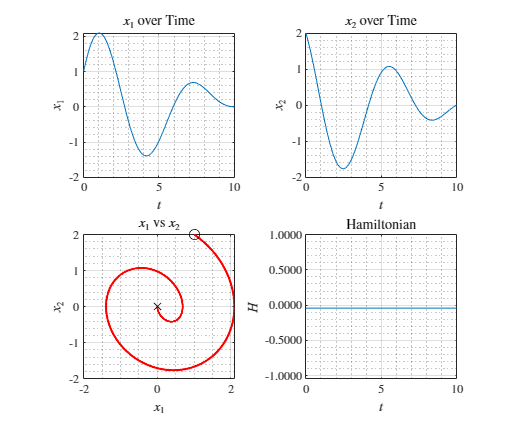

fig = figure("Renderer","painters","Position",[60 60 950 800]);
    % x1 vs t
    subplot(2,2,1)
    plot(tspan, x1sol)
    title('$x_1$ over Time')
    xlabel('$t$')
    ylabel('$x_1$')
    grid on; grid minor; box on;
    % x2 vs t
    subplot(2,2,2)
    plot(tspan, x2sol)
    title('$x_2$ over Time')
    xlabel('$t$')
    ylabel('$x_2$')
    grid on; grid minor; box on;
    % x1 - x2 
    subplot(2,2,3)
    plot(x1sol, x2sol,'-r',LineWidth=1.5)
    hold on;
    plot(x1sol(1),x2sol(1),'ok',MarkerSize=7)
    plot(x1sol(end),x2sol(end),'xk',MarkerSize=7)
    title('$x_1$ vs $x_2$')
    xlabel('$x_1$')
    ylabel('$x_2$')
    grid on; grid minor; box on; hold off;
    % Hamiltonian 
    subplot(2,2,4)
    plot(tspan, H(tspan))
    title('Hamiltonian')
    xlabel('$t$')
    ylabel('$H$')
    ytickformat('%,.4f')
    grid on; grid minor; box on;

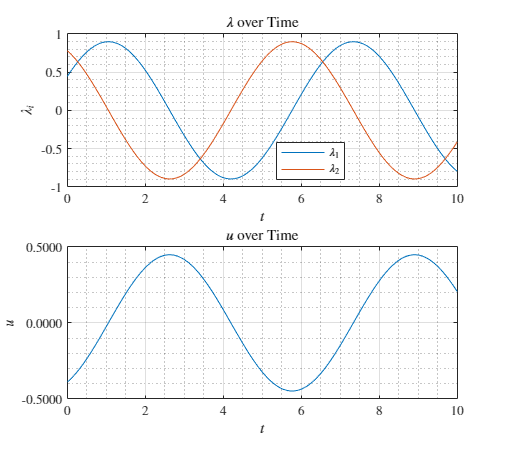

fig = figure("Renderer","painters","Position",[60 60 900 800]);
    % Plot costates 
    subplot(2,1,1)
    plot(tspan, lambda1,'DisplayName','$\lambda_1$')
    hold on;
    plot(tspan, lambda2,'DisplayName','$\lambda_2$')
    title('$\lambda$ over Time')
    xlabel('$t$')
    ylabel('$\lambda_i$')
    legend('Location','best'); grid on; grid minor; box on; hold off;
    % Plot control 
    subplot(2,1,2)
    plot(tspan, u(tspan))
    title('$u$ over Time')
    xlabel('$t$')
    ylabel('$u$')
    ytickformat('%,.4f')
    grid on; grid minor; box on;

function output = sym2array(input)
    N = length(input);
    ouput = zeros(N,1);
    for i = 1:N
        output(i) = double(input(i));
    end
end